# **Phase Locking Value (PLV)**

Leonardo Lancia

Laboratoire Parole et Langage 

CNRS / Aix Marseille Univesité

leonardo.lancia@cnrs.fr

Phase synchronization is a kind of coordination that affects the temporal behaviour of two systems but not necessarily the shape of the trajectory that the two systems follow. In this tutorial we illustrate how to quantify the degree of phase synchronization by estimating the phase locking value, which is an index of stability of the phase difference between two systems. If the two systems have two different oscillatory frequencies we can estimate the stability of their generalized phase difference.

**PLV and phase variability** The analysis is conducted by extracting the phase difference values from successive time intervals. Given two cyclic time series their phase difference or relative phase: $\phi_r =\phi_X -\phi_Y$, represents their relative lag in terms of relative cycle duration.

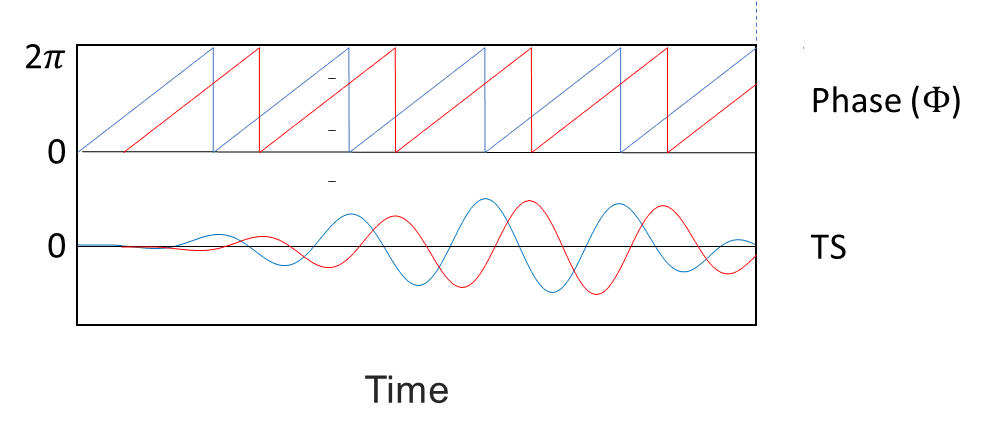

- Two signals are in phase ($\phi_r =0$) when they go up and down simultaneously. 

- They are in anti-phase  ($\phi_r =\pi$) when they move up and down in an alternated fashion.

- When $\phi_r =\phi_X -\phi_Y >0$, $Y$ lags $X$.

These phase relations are exemplified in the following figure.

clear
addpath(['./get_phase/utils'])
addpath(genpath('./gen_utils'))

t=[0:0.001:5];
A=-0.5.*(t.^3-5.*t.^2);
B=fliplr(A);
phi=wrapTo2Pi(2*pi*t);
c=A.*cos(phi);
d=B.*cos(phi);
e=B.*cos(phi+pi);   
f=A.*cos(phi+pi/2);
figure;
pl(1)=subplot(411);
plot(t,c); text(0.5,8,'A');
title('A and B are in-phase, B and C are anti-phase, D lags C ($phi_{C}-phi_{D}>0$)',...
    'interpreter','latex')
pl(2)=subplot(412);
plot(t,d);text(0.5,8,'B');
pl(3)=subplot(413);
plot(t,e);text(0.5,8,'C');
pl(4)=subplot(414);
plot(t,f);text(0.5,8,'D');

Anyway, in order to measure the degree of coordination, we are not interested in determining the average value of the relative phase, but its stability or, in other words, the degree of phase locking.

Such an index of coordination can thus be obtained for each considered interval by computing the variability of the phase difference values from their distribution. Phase difference values are angles, each associated to a vector of horizontal and vertical coordinates representing the corresponding point on the unit circle. Given a set of such N phase difference values:${\left\{{\textrm{∆}\phi }_1 ,\dots ,{\textrm{∆}\phi }_N \right\}}$, the Phase Locking Value (PLV) or Phase Synchronization Index (PSI) is equal to the length of the vector obtained by averaging the coordinate vectors corresponding to the points on the circle: 

$PSI={{\left\langle \cos {\textrm{∆}\Phi }_k \right\rangle }}_k^2 +{{\left\langle \sin {\textrm{∆}\Phi }_k \right\rangle }}_k^2 =\frac{1}{N}\left|{\sum e}^{\left(\Phi_A -\Phi_B \right)} \right|$                                           (1)

Where the brackets notation ${{\left\langle x_{i,k} \right\rangle }}_k$ indicates the average over values of $x_{i,k}$with different values for the index $k$. The rationale behind this computation is that the magnitude of the sum of two vectors increases as the difference between their orientations decreases. This can be seen in the following figure displaying two sets of unit length vectors starting from the origin and their averages (bold lines). Despite the lengths of the vectors are the same in the two plots, the average vectors’ lengths differ as a function of the variability in the orientations of the vectors.

figure
thetas=[pi/4, pi/3, pi*1.5, pi*2.8, pi.*1.8];
amps=[0.5,.4,.3,.7,.9];
thetas1=[pi/4, pi/3, pi/2.2, pi/7, pi.*1.8];
ampConst=ones(size(amps));

[ A , B ] = pol2cart( thetas , ampConst );
meanPoint=mean(A)+i*mean(B);
subplot(121)
drawPoints(ampConst,thetas,meanPoint)

subplot(122)
[ A , B ] = pol2cart( thetas1 , ampConst );
meanPoint=mean(A)+i*mean(B);
drawPoints(ampConst,thetas1,meanPoint)

In the computation of the PLV we must choose the length of the interval of time considered. Indeed, the variability of the relative phase depends on the rate of change of the phase angles. If the frequencies are slow enough and the adopted time window is too small it does not include enough time samples to display a sufficient amount of change in the two signals'phase. On the other hand, a two long time window may fail to reveal short time intervals in which the phase relation between the two analyzed oscillations is more stable. Therefore, it makes sense to conduct PLV analyses on time intervals whose durations depend on the rate of change of the instantaneous frequencies of the analyzed signals.

Let's load an EGG signal recording vocal folds' vibrations via two electrodes.


hiCut=500; %Max allowed frequency
lowCut=50; %Min allowed freq
filtOrd=5;%filter order

[audioSig,audioSr]=audioread(['./data/aska_1.wav']);

EGGsigDwn=resample(audioSig(:,3:4),1,10);
sr=audioSr/10;

EGGchunk=EGGsigDwn(23680:26210,:);
chunkT=[1:length(EGGchunk)]./sr;
figure;
plot(chunkT,EGGchunk)
xlabel('Time (secs)')
title('EGG channels')
set(gcf,'units','normalized','position',[0 0 0.5 0.27])

Before computing the instantaneous phases we band-pass filter the two signals.

% build filter coeffs
hiCutNorm=hiCut./( sr/2 );
lowCutNorm=lowCut./( sr/2 );
[b1,a1]=butter(filtOrd,[lowCutNorm hiCutNorm]);

% filter signals
filtSig1=filtfilt(b1,a1,EGGchunk(:,1)); 
filtSig2=filtfilt(b1,a1,EGGchunk(:,2));

figure;
subplot(211)
plot(chunkT ,filtSig1)
title('Filtered EGG channels')
subplot(212)
plot(chunkT, filtSig1)
xlabel('Time (secs)')

Now we can then normalize their cycles amplitudes, apply the Hilbert transform and get the phase values.

% apply amplitude normalization from Huang et al (2009)
filtSigNorm1=normalize_env_peaks(filtSig1);
filtSigNorm2=normalize_env_peaks(filtSig2);

% compute the phase of the output of Hilbert.m
theta1=angle(hilbert(filtSigNorm1));
theta2=angle(hilbert(filtSigNorm2));


figure;
ppp(1)=subplot(411);
plot(chunkT,filtSig1)
title('Filtered first EGG channel')
ppp(2)=subplot(412);
plot(chunkT,theta1')
title('First EGG channel phase')
ppp(3)=subplot(413);
plot(chunkT,filtSig2);
title('Filtered second EGG channel')
ppp(4)=subplot(414);
plot(chunkT,theta2')
title('Second EGG channel phase')
linkaxes(ppp,'x')
xlabel('Time (secs)')

The function get_PLV.m processes small chunks of signals by sliding a window with a constant step. In this way it is possible to obtain a time varying measure of phase locking.

Note that the definition of phase difference is strictly related to the assumption that the two signals have the same frequency of oscillation.  The generalized phase difference:

$\phi_R =m\times \phi_X -n\times \phi_Y$.                                                                                  (2)

however can be applied also to signals that differ in terms of oscillatory frequencies. Here $m$ and $n$ are such that their ratio is equal to the ratio between the frequencies of the two signals.

In order to estimate $m$ and $n$ without knowing the oscillatory frequencies of the signals, we assume that they are positive integers up to a given ceil value (usually 10)  and we chose the pair of integers that gives the highest PLV. This operation can be repeated at each analysis window.

The parameters for the extraction of the PLV are the following:

**thetha1**: first vector of phase values

**theta2**: second vector of phase values

**winLen**: analysis window length in frames. (Optional; default val.: 0 indicating the duration of the input signal)

**winStep**: analysis window step in frames. (Optional; default val.: 0 indicating that only one time-window is considered)

**maxOrd**: if this is a scalar, it represent the maximum value for the m and n coefficients that are estimated at each analysis window. If this is 2-values vector the two coefficients m and n are fixed at the given values. (Optional; default val.: 10)

The function outputs the PLVs computed, their time anchors (in time steps), the optimal values for the n coefficients and the optimal values for the m coefficients.

winLen=fix(length(EGGchunk)/30);%analysis window length to compute the PLV
winStep=fix(winLen/10); %step size to compute the PLV
maxord=10; % maximum value for the numerator and the denominator of the
           % ratio between the signals' frequencies.
[PLVvals,PLVtStep,opt_n,opt_m]=get_PLV(theta1,theta2,winLen,winStep,maxord); %compute the PLV

figure
pppp(1)=subplot(211);
plot(chunkT,EGGchunk)
title('EGG channels')
pppp(2)=subplot(212);
plot(chunkT(PLVtStep),PLVvals)
title('Phase Locking Value (PLV)')
xlabel('Time (secs)')

function drawPoints(amps,thetas,meanPoint)
    [ A , B ] = pol2cart( thetas , amps );
    for ii=1:length(thetas)
        polarplot(repmat(thetas(ii),1,2),[0,amps(ii)],'Color','k');
        hold on
        polarplot(thetas(ii),amps(ii),'Color','k','Marker','o');
    end
    meanRho=sqrt(real(meanPoint)^2+imag(meanPoint)^2);
    meanTheta=atan(imag(meanPoint)^2/real(meanPoint)^2);
    polarplot(repmat(meanTheta,1,2),[0,meanRho],'LineWidth',3,'Color','k')
    polarplot(meanTheta,meanRho,'LineWidth',3,'Color','k','Marker','o')
    myAx=gca;
    myAx.ThetaAxisUnits = 'radians';
    thetaticks([0 pi/2 pi (3/2)*pi 2*pi])
    rticklabels({});
end